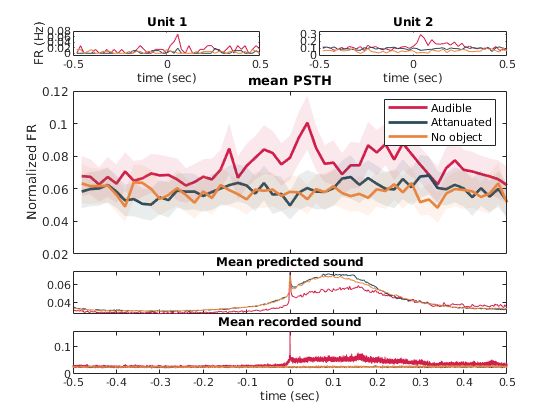

subplot(6,2,1)
plot(time_vecor,psth_alum_aud(11,:),'Color',FVB103_849.experiment.color.Aluminum); 
hold on; 
plot(time_vecor,psth_mut_aud(11,:),'Color',FVB103_849.experiment.color.Muted); 
plot(time_vecor,psth_non_aud(11,:),'Color',FVB103_849.experiment.color.noObject); 
title('Unit 1')
xlabel('time (sec)')
ylabel('FR (Hz)')
ylim([-0.01 0.08])
subplot(6,2,2)
plot(time_vecor,psth_alum_aud(32,:),'Color',FVB103_849.experiment.color.Aluminum); 

hold on; 
plot(time_vecor,psth_mut_aud(32,:),'Color',FVB103_849.experiment.color.Muted); 
plot(time_vecor,psth_non_aud(32,:),'Color',FVB103_849.experiment.color.noObject);
title('Unit 2')
xlabel('time (sec)')
ylim([-0.01 0.35])
subplot(6,2,3:8)
plot_areaerrorbar(psth_alum_aud,optionsAl)
hold on
plot_areaerrorbar(psth_mut_aud,optionsMu)
hold on
plot_areaerrorbar(psth_non_aud,optionsNo)
title('mean PSTH')
ylabel('Normalized FR')
legend('','Audible','','Attanuated','','No object')
set(gca,'xticklabel',[])

subplot(6,2,9:10)
plot(predTimeVector,aluminumPredicted,'Color',FVB103_849.experiment.color.Aluminum)
hold on
plot(predTimeVector,mutedPredicted,'Color',FVB103_849.experiment.color.Muted)
plot(predTimeVector,nonPredicted,'Color',FVB103_849.experiment.color.noObject)
set(gca,'xticklabel',[])
title('Mean predicted sound')
subplot(6,2,11:12)
plot(epTimeVector,aluminumReal,'Color',FVB103_849.experiment.color.Aluminum)
hold on
plot(epTimeVector,mutedReal,'Color',FVB103_849.experiment.color.Muted)
plot(epTimeVector,nonReal,'Color',FVB103_849.experiment.color.noObject)
xlabel('time (sec)')
title('Mean recorded sound')

Sound_mean_1 = mean(abs(FVB103_757.experiment.sound_events.fullSound(aluminumReal_757)))

Sound_mean_1 =     0.0275    0.0269    0.0253    0.0272    0.0272    0.0277    0.0246    0.0287    0.0322    0.0298    0.0266    0.0212    0.0241    0.0255    0.0320    0.0253    0.0249    0.0252    0.0257    0.0230    0.0298    0.0303    0.0297    0.0229    0.0272    0.0262    0.0312    0.0290    0.0260    0.0286    0.0281    0.0248    0.0293    0.0291    0.0243    0.0264    0.0247    0.0279    0.0301    0.0260    0.0281    0.0261    0.0263    0.0295    0.0303    0.0302    0.0288    0.0265    0.0262    0.0277


Sound_mean_2 = mean(abs(FVB103_849.experiment.sound_events.fullSound(aluminumReal_849)))

Sound_mean_2 =     0.0388    0.0421    0.0449    0.0465    0.0414    0.0338    0.0409    0.0421    0.0486    0.0462    0.0353    0.0405    0.0370    0.0424    0.0540    0.0436    0.0360    0.0381    0.0420    0.0457    0.0449    0.0450    0.0426    0.0388    0.0448    0.0443    0.0460    0.0436    0.0400    0.0372    0.0386    0.0416    0.0443    0.0444    0.0376    0.0387    0.0412    0.0457    0.0463    0.0469    0.0397    0.0416    0.0407    0.0409    0.0491    0.0482    0.0423    0.0375    0.0406    0.0467


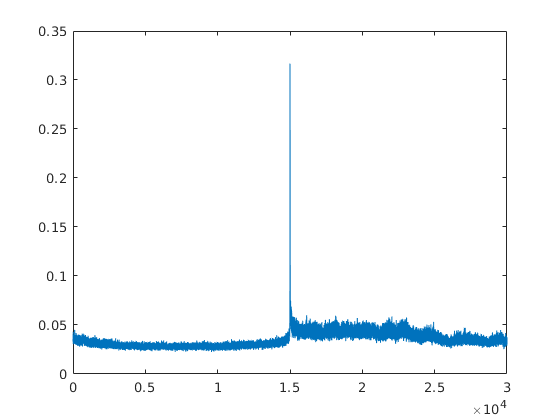

figure;
Sound_mean = (Sound_mean_2 + Sound_mean_1)/2;
plot(Sound_mean)

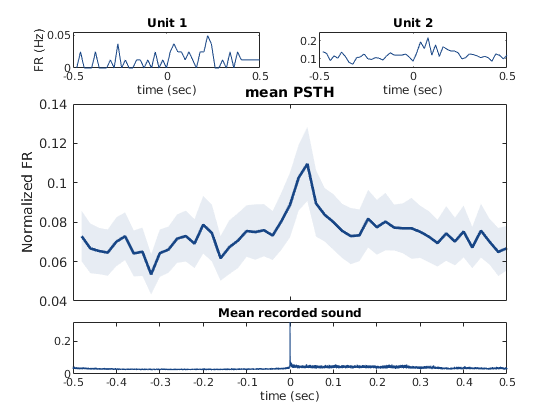

figure;
subplot(5,2,1)
plot(time_vecor,both_psth(11,:),'Color',[0.09,0.27,0.52])
ylim([-0.01 0.08])
title('Unit 1')
xlabel('time (sec)')
ylabel('FR (Hz)')
ylim([0 0.055])
subplot(5,2,2)
plot(time_vecor,both_psth(32,:),'Color',[0.09,0.27,0.52])
ylim([-0.01 0.35])
title('Unit 2')
xlabel('time (sec)')
ylim([0.05 0.25])
subplot(5,2,3:8)
optionsS.handle = figure(2);
optionsS.error = 'sem';
optionsS.color_area = [0.09,0.27,0.52];   
optionsS.color_line = [0.09,0.27,0.52];   
optionsS.alpha = 0.1;        
optionsS.line_width = 2;   
optionsS.x_axis = time_vecor;
plot_areaerrorbar(both_psth,optionsS)
title('mean PSTH')
ylabel('Normalized FR')
set(gca,'xticklabel',[])

subplot(5,2,9:10)
plot(epTimeVector,Sound_mean,'Color',[0.09,0.27,0.52])
title('Mean recorded sound')
xlabel('time (sec)')


subplot(10,3,[19:24])
plot(predTimeVector,aluminumPredicted,'Color',FVB103_849.experiment.color.Aluminum)
hold on
plot(predTimeVector,mutedPredicted,'Color',FVB103_849.experiment.color.Muted)
plot(predTimeVector,nonPredicted,'Color',FVB103_849.experiment.color.noObject)
ylim([0 0.15])



subplot(10,3,[25:30])
plot(epTimeVector,aluminumReal,'Color',FVB103_849.experiment.color.Aluminum)
hold on
plot(epTimeVector,mutedReal,'Color',FVB103_849.experiment.color.Muted)
plot(epTimeVector,nonReal,'Color',FVB103_849.experiment.color.noObject)
ylim([0 0.15])

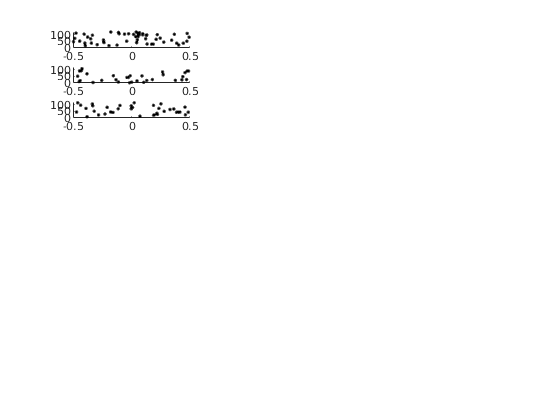

figure;
subplot(10,3,1)
createRaster(FVB103_757.experiment.sound_events.aluminumEvents,FVB103_757.experiment.Units.mua.times(12,:),1);
ylim([0 120])
subplot(10,3,4)
ylim([0 120])
createRaster(FVB103_757.experiment.sound_events.mutedEvents,FVB103_757.experiment.Units.mua.times(12,:),1);
subplot(10,3,7)
ylim([0 120])
createRaster(FVB103_757.experiment.sound_events.nonEvents,FVB103_757.experiment.Units.mua.times(12,:),1);

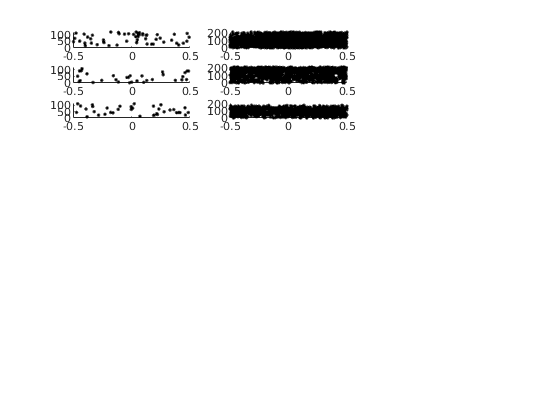

subplot(10,3,2)
createRaster(FVB103_849.experiment.sound_events.aluminumEvents,FVB103_849.experiment.Units.good.times(6,:),1);
ylim([0 220])
subplot(10,3,5)
ylim([0 220])
createRaster(FVB103_849.experiment.sound_events.mutedEvents,FVB103_849.experiment.Units.good.times(6,:),1);
subplot(10,3,8)
ylim([0 220])
createRaster(FVB103_849.experiment.sound_events.nonEvents,FVB103_849.experiment.Units.good.times(6,:),1);

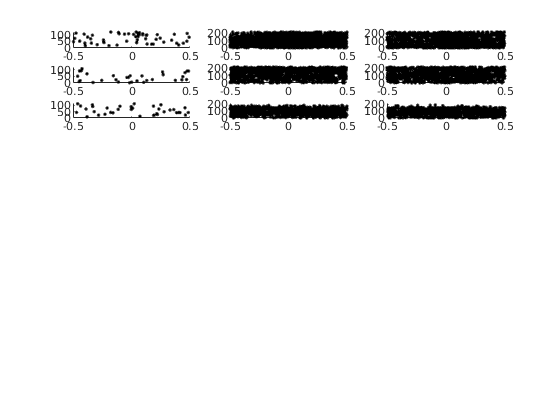

subplot(10,3,3)
createRaster(FVB103_849.experiment.sound_events.aluminumEvents,FVB103_849.experiment.Units.mua.times(1,:),1);
ylim([0 220])
subplot(10,3,6)
ylim([0 220])
createRaster(FVB103_849.experiment.sound_events.mutedEvents,FVB103_849.experiment.Units.mua.times(1,:),1);
subplot(10,3,9)
ylim([0 220])
createRaster(FVB103_849.experiment.sound_events.nonEvents,FVB103_849.experiment.Units.mua.times(1,:),1);


for i = 1: length(psth_alum_aud)
    figure;
    plot(psth_alum_aud(41,:))
    title(['number ',num2str(i)])
end

for i = 1:42
    figure;
    plot(psth_mut_aud(i,:))
    title(['number ',num2str(i)])
end


[aluminum_predict_vector_757,ia_757,ib_757] = intersect(aluminum_vector_757,FVB103_757.experiment.predictedSound.sampleVector)

aluminum_predict_vector_757 = 124276×1 int64 column vector
   4861876
   4861953
   4862023
   4862100
   4862179
   4862253
   4862327
   4862406
   4862476
   4862552


ia_757 =     59
   136
   206
   283
   362
   436
   510
   589
   659
   735


ib_757 =        63758
       63759
       63760
       63761
       63762
       63763
       63764
       63765
       63766
       63767


[aluminum_predict_vector_849,ia_849,ib_849] = intersect(aluminum_vector_849,FVB103_849.experiment.predictedSound.sampleVector)

aluminum_predict_vector_849 = 124275×1 int64 column vector
   14291262
   14291333
   14291409
   14291487
   14291562
   14291635
   14291710
   14291793
   14291864
   14291936


ia_849 =     35
   106
   182
   260
   335
   408
   483
   566
   637
   709


ib_849 =       189246
      189247
      189248
      189249
      189250
      189251
      189252
      189253
      189254
      189255


predict_sound = [FVB103_757.experiment.predictedSound.y(ib_757);FVB103_849.experiment.predictedSound.y(ib_849)]

predict_sound =     0.0192
    0.0133
    0.0423
    0.0202
    0.0282
    0.0375
    0.0219
    0.0256
    0.0493
    0.0220


real_sound = [FVB103_757.experiment.sound_events.fullSound(aluminum_predict_vector_757),FVB103_849.experiment.sound_events.fullSound(aluminum_predict_vector_849)]

real_sound =     0.0063    0.0027    0.0703    0.0057    0.0297    0.0622    0.0152    0.0442    0.0658    0.0038    0.0428    0.0302    0.0298    0.0317    0.0003    0.0227    0.0276    0.0336    0.0166    0.0195    0.0315    0.0186    0.0126    0.0074    0.0387    0.0467    0.0307    0.0012    0.0212    0.0118    0.0378    0.0168    0.0248    0.0352    0.0592    0.0428    0.0292    0.0068    0.0548    0.0432    0.0202    0.0512    0.0388    0.0692    0.0332    0.0562    0.0682    0.0388    0.0152    0.0098


[r,lags] = xcorr(predict_sound,real_sound,'normalized')

r =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


lags =      -248550     -248549     -248548     -248547     -248546     -248545     -248544     -248543     -248542     -248541     -248540     -248539     -248538     -248537     -248536     -248535     -248534     -248533     -248532     -248531     -248530     -248529     -248528     -248527     -248526     -248525     -248524     -248523     -248522     -248521     -248520     -248519     -248518     -248517     -248516     -248515     -248514     -248513     -248512     -248511     -248510     -248509     -248508     -248507     -248506     -248505     -248504     -248503     -248502     -248501


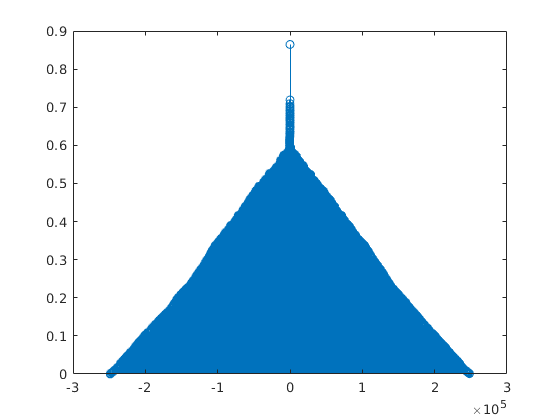

figure
stem(lags,r)